# Laboratorio 8 Control Discreto - Discreto

k=0.7;
tao=1;

tm=4*tao/50

tm = 0.0800


plantaContinua=tf(k,[tao 1])

plantaContinua =
 
   0.7
  -----
  s + 1
 
Continuous-time transfer function.



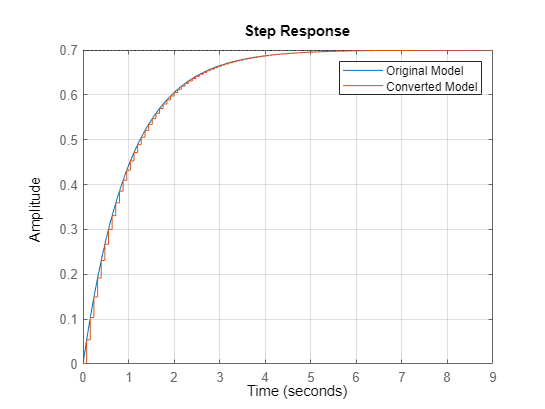

% Convert model from continuous to discrete time
plantaDis = c2d(plantaContinua,0.08);

% Visualize the results
stepplot(plantaContinua,plantaDis);
legend('Original Model','Converted Model');
grid on;

plantaDis

plantaDis =
 
   0.05382
  ----------
  z - 0.9231
 
Sample time: 0.08 seconds
Discrete-time transfer function.



[B,A]=tfdata(plantaDis,'v')

B =          0    0.0538


A =     1.0000   -0.9231



syms r0 r1 r2 z

B=poly2sym(B,z)

$$B = \frac{3878035770157129}{72057594037927936}$$

A=poly2sym(A,z)

$$A = z-\frac{8314692867212933}{9007199254740992}$$

R=r0*z^2+r1*z+r2;
S=collect((z-1)*(z-1),z)

$$S = z^{2}-2\,z+1$$


% polinomio deseado

zd=0.9;
tsd=2;
wnd=4/(zd*tsd)

wnd = 2.2222

p1=-2*exp(-zd*wnd*tm)...
    *cos(wnd*tm*sqrt(1-zd^2));
p2= exp(-2*zd*wnd*tm);

poldes=vpa(collect((z^2+p1*z+p2)*(z-0.1),z),4)

$$poldes = z^{3}-1.799\,z^{2}+0.8961\,z-0.07261$$


polcarac=vpa(collect(B*R+A*S,z),4)

$$polcarac = z^{3}+\left(0.05382\,r_{0}-2.923\right)\,z^{2}+\left(0.05382\,r_{1}+2.846\right)\,z+0.05382\,r_{2}-0.9231$$


sol=vpa(coeffs(polcarac,z)==coeffs(poldes,z),4)

$$sol = \left(\begin{array}{cccc} 0.05382\,r_{2}-0.9231=-0.07261 & 0.05382\,r_{1}+2.846=0.8961 & 0.05382\,r_{0}-2.923=-1.799 & 1.0=1.0 \end{array}\right)$$

sol=solve(sol)

sol = struct with fields:
    r0: 20.883935407616844890612272023266
    r1: -36.23594608458448604493421884738
    r2: 15.803125942491594154095763529629



r0=double(sol.r0)

r0 = 20.8839

r1=double(sol.r1)

r1 = -36.2359

r2=double(sol.r2)

r2 = 15.8031


[B,A]=tfdata(plantaDis,'v') 

B =          0    0.0538


A =     1.0000   -0.9231
